# Wiener Filter

- Wiener Filters are Filters which restore a distorted signal in an "optimal" sense. 

- Optimal = they generate a signal that has the least mean squared error when compared to the original

- the signals have to be stationary

clc;
clear ans idx n gamma_ss gamma_vv;
close all;

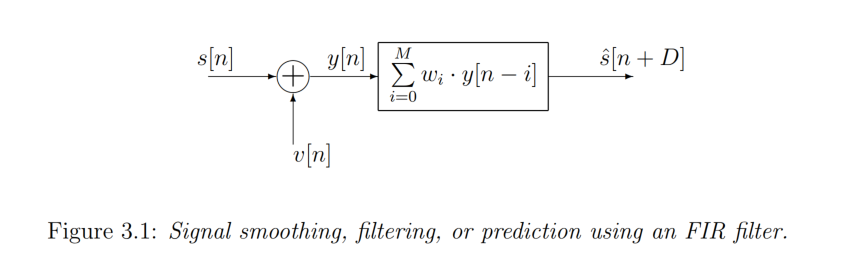

- s[n] = original Signal = unknown = independent, zero mean, stationary process

- v[n] = noise = unknown = independent, zero mean stationary process

- y[n] = input signal = superposition noise and original signal

- w_i = filtercoefficients, should be chosen so that output is optimal estimate of original signal

- s_hat[n+D]= original signal estimation, D = integer Constant

- D>0: Eliminate noise from signal, smoothing

- D=0: estimate original signal in realtime

- D<0: forecast the future of the signal

- INPUT: y[n]=s[n]+v[n]

- OUTPUT:

- ERROR:                    

                                        

- MeanSquaredError: 

                                

####      Wiener Hopf Equations                          

The goal is to find the minimal MSE. The coefficients w_i represent a Signal which if convoluted wit the input results in a Signal with minimal MSE. So the goal is to find these filtercoefficients. The mean squared error can be regarded as e series of equations of which w_i coefficents ar the independent variables (MSE equation above). The derivative of all these equations results in the gradient. Minima can be found by setting the gradient to 0. More has to be taken into consideration though. As input, the autocorrelation y[n]l will be chosen. According to the Wiener–Khinchin theorem this enables us to do a spectral analysis. How it is derived will be treated seperately for now lets just consider this: 

    

The optimum is where the autocorrelation of the input signal multiplied with a constant is the same as the corsscorrelation of the inputsignal with the original or desired signal. The equation above represents the wiener hopf equations

  

Now the Sum above can be rewritten as:

                  ,

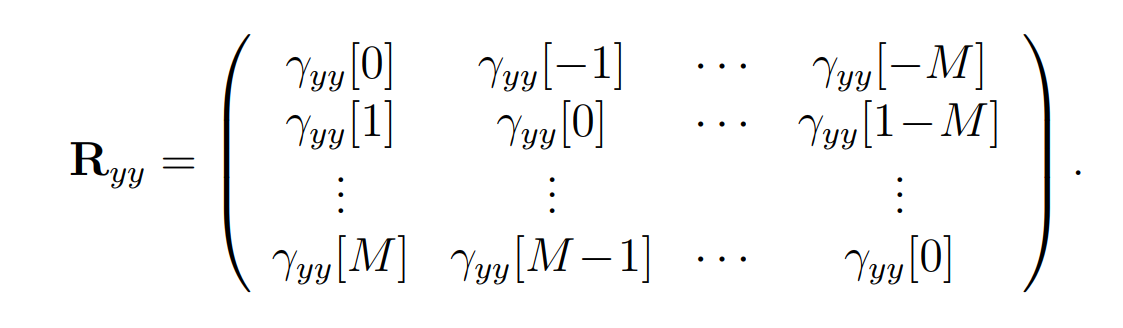

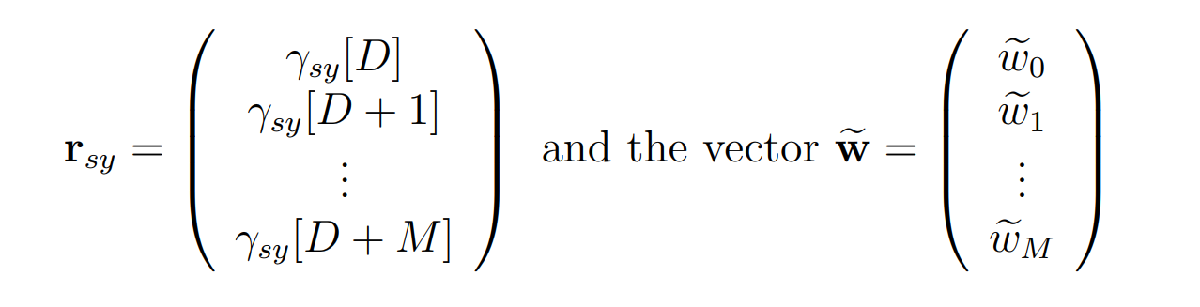

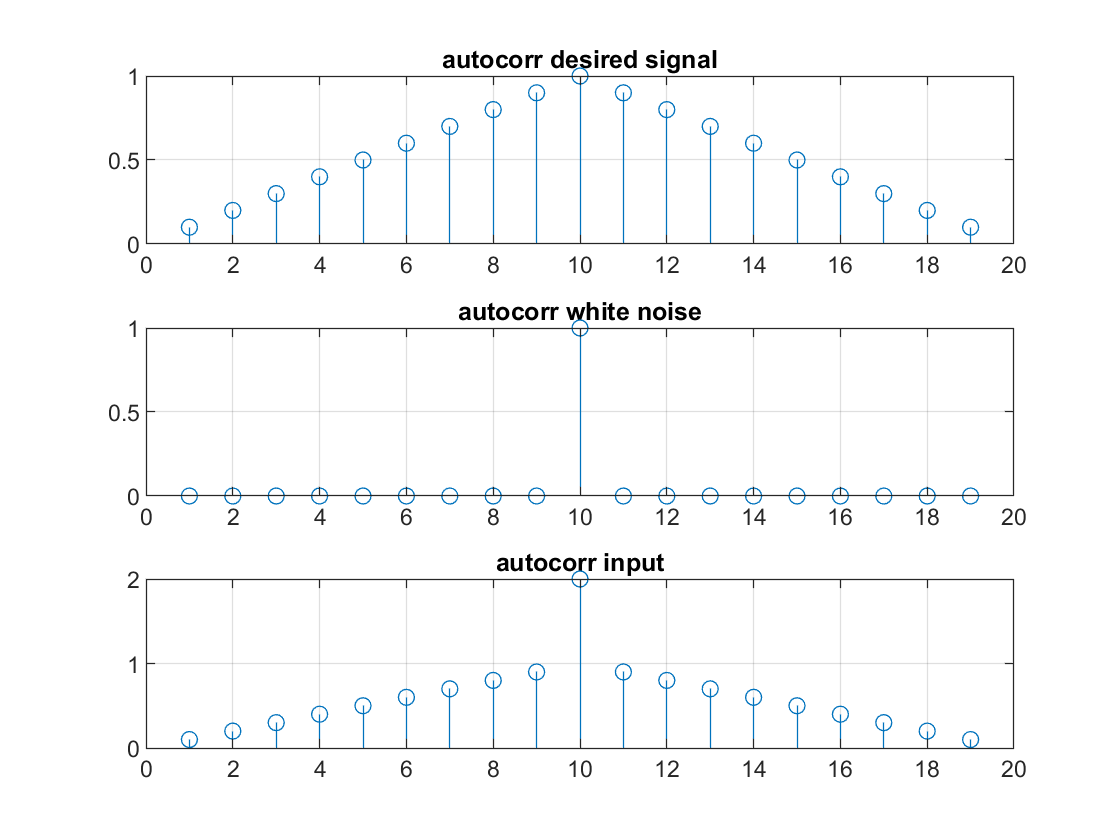

M=10;%because matlab indexin starts at 1 
m=length(xcorr(1:10,1:10));
n=ones(1,m);
%define autocorr of zero-mean random signal
gamma_ss=n;
for idx=1:length(n)/2+1
    gamma_ss(idx)=n(idx)*0.1*idx;
end
gamma_ss=fliplr(gamma_ss);
for idx=1:length(n)/2
    gamma_ss(idx)=n(idx)*0.1*idx;
end
% define autocorr of white noise signal
gamma_vv=zeros(1,m);
gamma_vv(m/2+0.5)=1;
gamma_yy=gamma_ss+gamma_vv;

figure;
subplot(3,1,1)
stem(gamma_ss)
title('autocorr desired signal')
grid on;
subplot(3,1,2)
stem(gamma_vv)
title('autocorr white noise')
grid on;
subplot(3,1,3)
stem(gamma_yy)
title('autocorr input')
grid on;

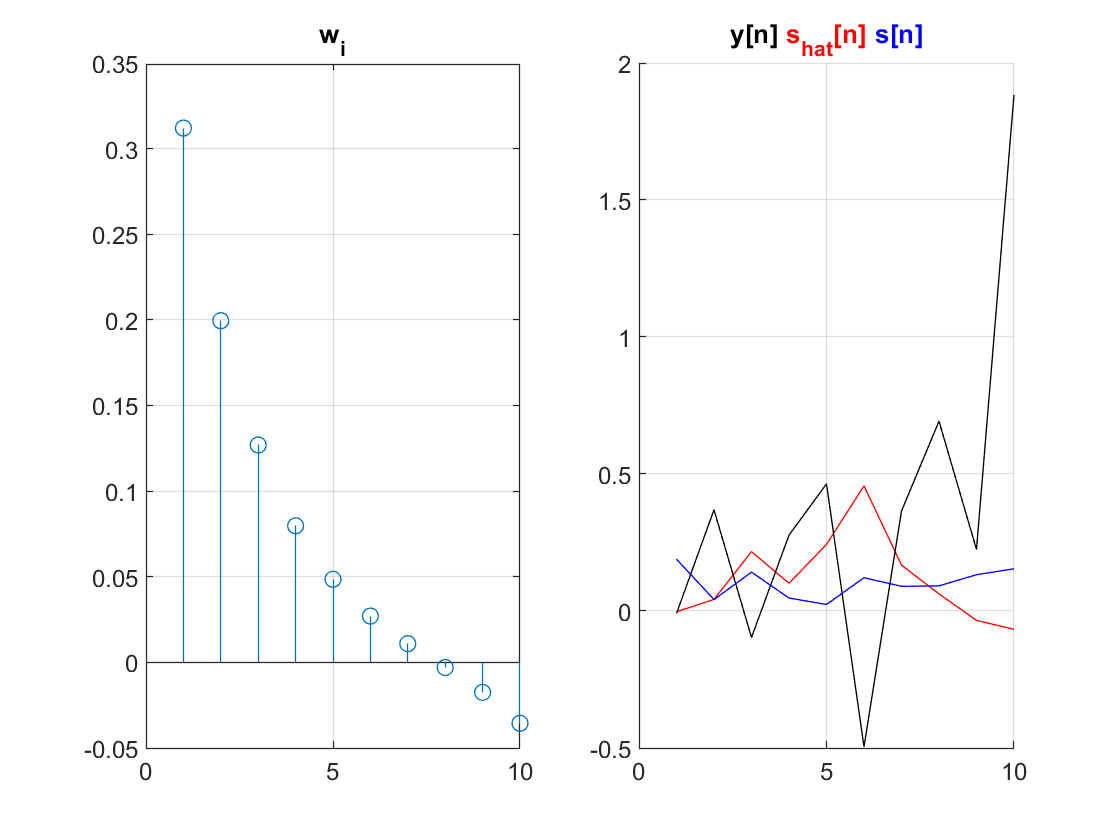

D=0;
%R_yy
R_yy=[gamma_yy(10:19);
      gamma_yy(9:18);
      gamma_yy(8:17);
      gamma_yy(7:16);
      gamma_yy(6:15);
      gamma_yy(5:14);
      gamma_yy(4:13);
      gamma_yy(3:12);
      gamma_yy(2:11);
      gamma_yy(1:10)];
%special case where s[n] is superimposed by white noise therefore
%gamma_ss=gamma_sy
r_sy=gamma_ss(10:19)';
%w_approx=R_yy^-1*r_sy -> filtercoefficients
w_approx=inv(R_yy)*r_sy;
%impulseresponse filter
h=w_approx';


%create original signal
if false
    %rectangular function, since xcorr of this gives the demanded
    %autocorrelation
    s_n=1/10*[1 1 1 1 1 1 1 1 1 1]
elseif true
        s_n=1/10*[1 1 1 1 1 1 1 1 1 1].*(2*rand(1,10));
else
    %jsut to experiment
    s_n=sin(0:2*pi/10:2*pi-2*pi/10)
end
%create white noise signal
v_n=randn(1,10);
%create input signal
y_n=s_n+v_n;
%create estimation by filtering 
s_hat=downsample(conv(y_n,h),2);

figure;
subplot(1,2,1)
stem(w_approx)
title('w_i')
grid on;
subplot(1,2,2)
hold on;
plot(s_hat,"Color",'red')
plot(y_n,"Color",'black')
plot(s_n,"Color",'blue')
hold off;
grid on;
title(['y[n] {\color{red}s_{hat}[n] \color{blue}s[n]}'])

### Questions:

- why isnt s_n a rectangular function in the script?

- how do we ajust the length? there are 10 filtercoefficients so, how do we compare the signals properly?

- convolution leads to doubling the length...

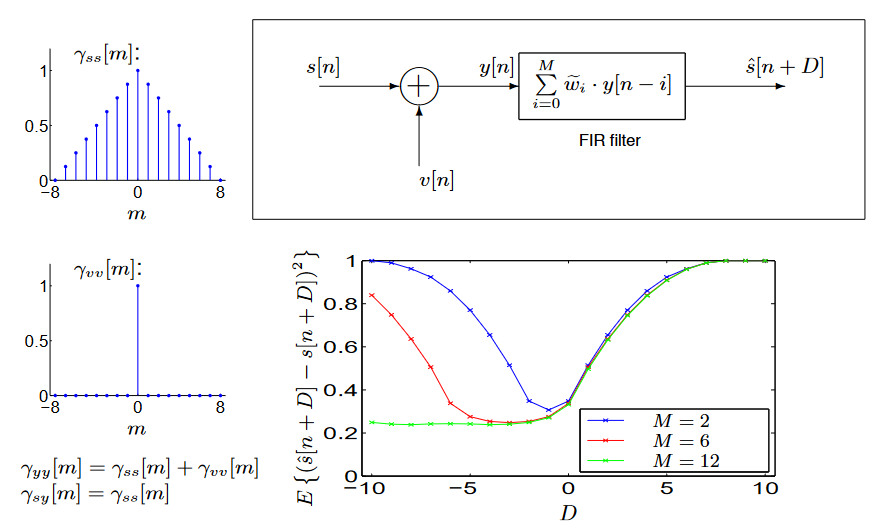

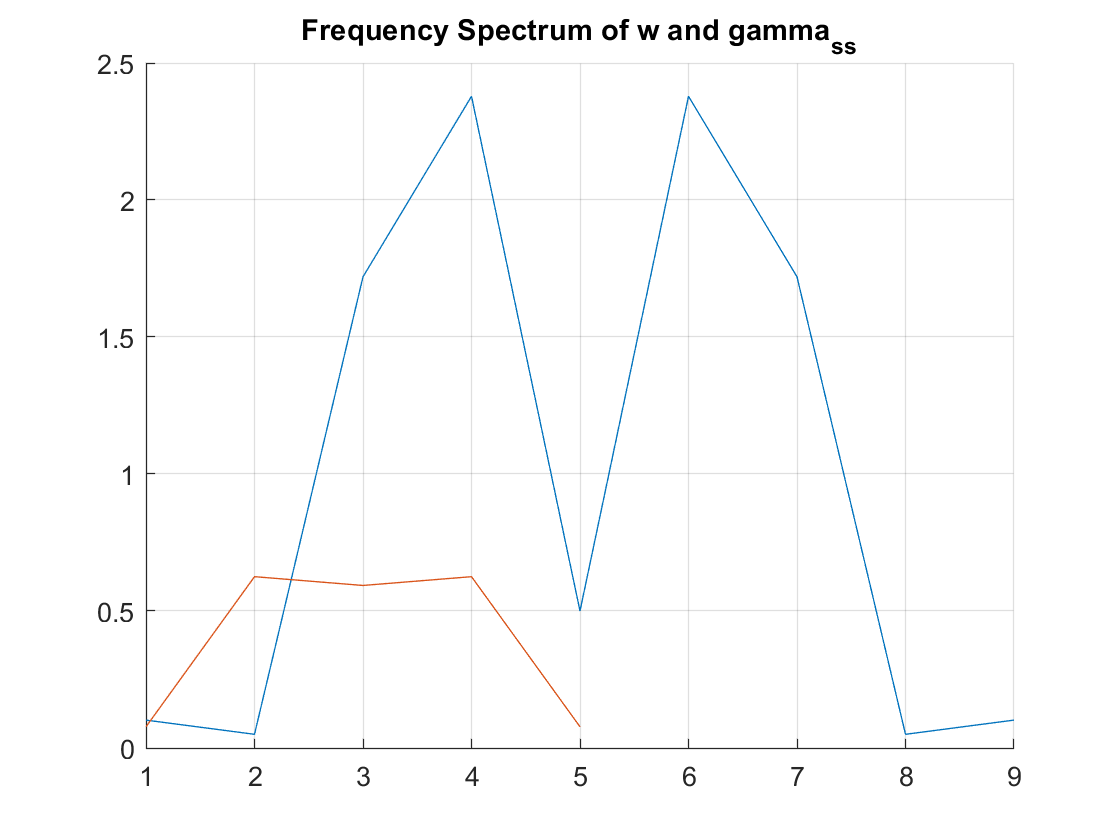

s_n=[1 1 1 1 1 1 1 1 1];
%define Signals
gamma_ss=1/8*xcorr(s_n,s_n)-1/8;
gamma_vv=zeros(1,17);
gamma_vv(9)=1;
gamma_yy=gamma_ss+gamma_vv;
gamma_sy=gamma_ss%special case addition of white noise

%define coefficients
M1=2+1;%+1 because matlab indexing starts at 1 not at 0 so the true length of the vector M is plus 1, [0 1 2] = [1 2 3]
M2=5+1;
M3=8+1;

R_yy=toeplitz(gamma_yy);
R_yy=R_yy(9:length(R_yy),1:9);
R_yy_M1=R_yy(1:M1,1:M1);
R_yy_M2=R_yy(1:M2,1:M2);
R_yy_M3=R_yy(1:M3,1:M3);

w_M1=R_yy_M1*gamma_sy(1:M1)';
w_M2=R_yy_M2*gamma_sy(1:M2)';
w_M3=R_yy_M3*gamma_sy(1:M3)';

s_hat_M1=conv(w_M1,gamma_yy)*1/length(conv(w_M1,gamma_yy));
s_hat_M2=conv(w_M2,gamma_yy)*1/length(conv(w_M2,gamma_yy));
s_hat_M3=conv(w_M3,gamma_yy)*1/length(conv(w_M3,gamma_yy));

figure
hold on;
plot(gamma_yy-s_hat_M1(2:length(s_hat_M1)-1));
plot(gamma_yy-s_hat_M2);
plot(gamma_yy-s_hat_M3);

hold off;

- Not working at all

- why not symmetric?

- no idea where mistake is...

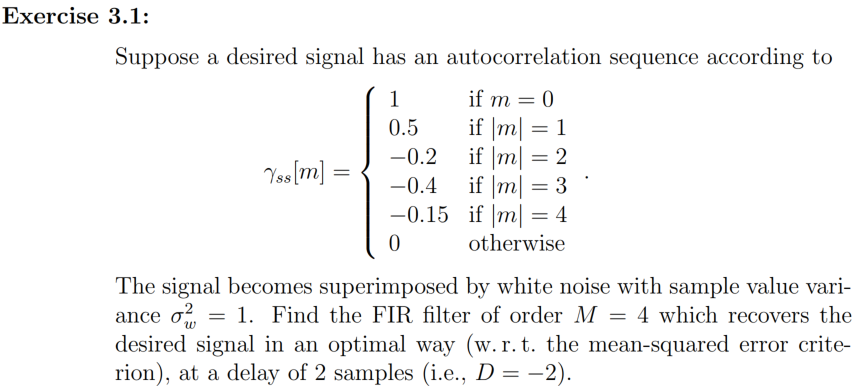

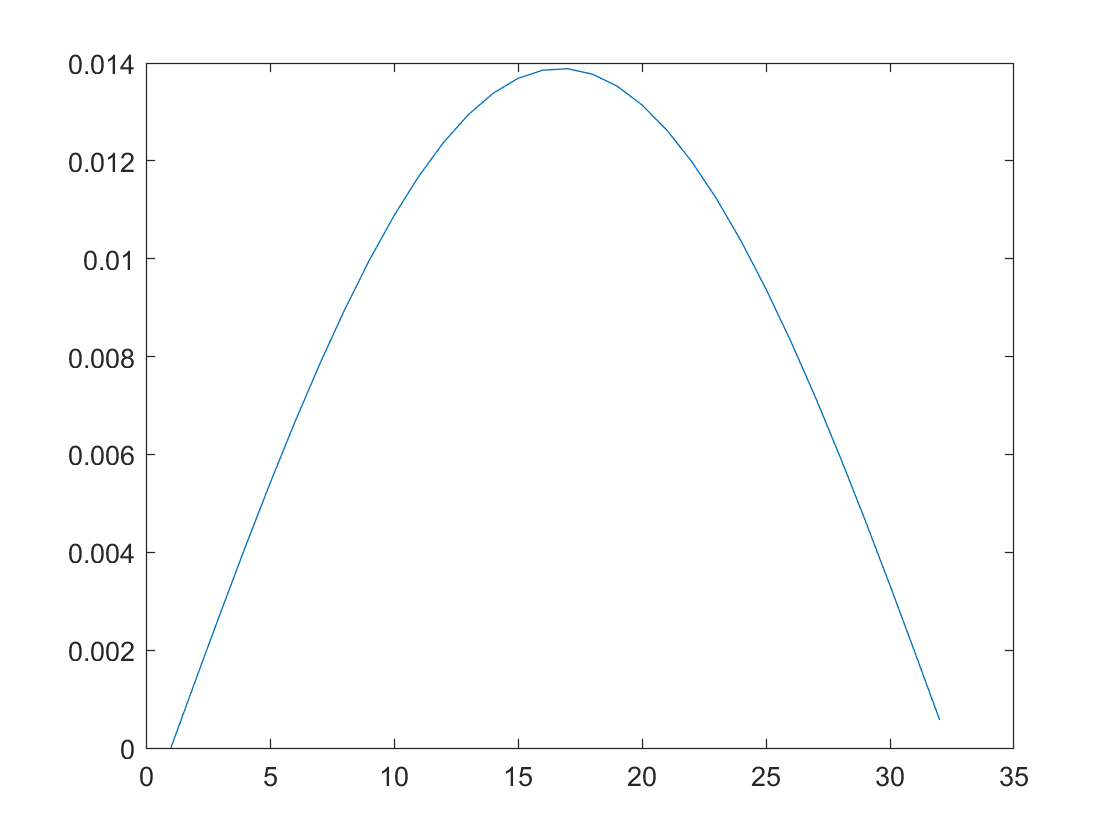

gamma_ss=[-0.15 -0.4 -0.2 0.5 1. 0.5 -0.2 -0.4 -0.15];
%again the assumption is, that  r_sy=gamma_ss 
if false
r_sy=gamma_ss(5:9);%no delay
else
r_sy=gamma_ss(3:7);%with delay
end

% define autocorr of white noise signal
gamma_vv=zeros(1,length(gamma_ss));
gamma_vv(length(gamma_ss)/2+0.5)=1;
gamma_yy=gamma_ss+gamma_vv;
%define matrix R_yy
R_yy=toeplitz(gamma_yy);
M=4+1;%matlab starts indexing at 1 not 0 
R_yy=R_yy(5:9,1:5);
w_approx=inv(R_yy)*r_sy';
%generate frequency response
omega=[-pi:0.01:pi];
if false
    freq_resp=real(gamma_ss*exp(-i*(-4:4)'*omega));
    filter_freq_resp=abs(w_approx'*exp(-i*(0:4)'*omega))
else
    freq_resp=fftshift(abs(fft(gamma_ss)));
    filter_freq_resp=fftshift(abs(fft(w_approx')));
end
figure;
hold on
plot(freq_resp)
plot(filter_freq_resp)
hold off;
grid on; 
title('Frequency Spectrum of w and gamma_{ss}')

- not sure how the transformation works after the if condition 

- not sure how to shift the spectrum properly after the else

- overall not sure why we look at the spectrum? not sure if correct

### Unconstrained Wiener Filter

changes to the formula above:

- i goes from -infinity to infinity, D=0

- translation to Z domain

Def. Unconstrained Wiener Filter: 

Special Case, Additive noise: 

if: 

then:

resp.

A=1;%desired signal
B=71;%additive noise

sig=sin([0:0.1:pi]);
T=A/(A+B);
figure;
plot(sig*T);

- The noisier the signal (more noise power in spectrum) the more the signal will be dampened by the filter.

- in the case of white noise, the anticausal part of the filter can be omitted, since noise whitening apparently doesn't affect the filterperformance this method promises a straight forward way on designing optimal wiener filters

- How does that affect the aformentioned described method? don't get it...